Task 0

I dont mind if the lecture is digital or physical, but I would really like if the lectures are recorded as the lecture collides with something else for me. I read the powerpoints but I dont feel like this is sufficent. 

And I think either the assignments should be out earlier or the assignment lecture should be moved to monday or tuesday, as the time from getting the assignment to the assignment lecture/aid is very short.

Loading in the files and setting global variables given in assignment.

invivo_data = load("invivoData.mat");
sim_data = load("simdata.mat");
c = 1540;

Task 1

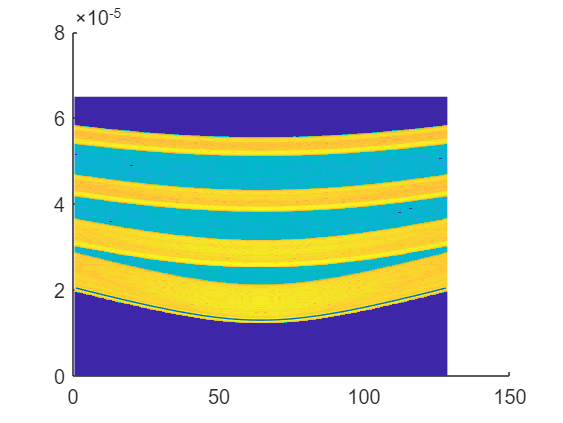

sim_elpos = sim_data.elPosX;
sim_Rf = sim_data.RFdata;
sim_Rf_t = sim_data.RF_t;
x1 = 0;
z1 = 0.01; %meter
TOF_sim = TOF(z1,c,x1,sim_elpos);
[sim_rows, sim_cols] = size(sim_Rf);
sim_xaxis = linspace(1,sim_cols,sim_cols);
%colormap(gray(256));
%imagesc(sim_Rf');
imagesc('XData',sim_xaxis,'YData',sim_Rf_t,'CData', log(abs(sim_Rf)));
hold on;
plot(TOF_sim);


x = linspace( -2e-2, 2e-2, 256); %x-coordinates
zlen = 512;
z = linspace( 0, 4.5e-2, zlen); %z-coordinates
z = permute(z, [1 3 2]);
[X, Z] = meshgrid( x, z); %make X and Z matrices
% initialize TOF-matrix
TOF_sim_mat = zeros( length(z), length(x), length(sim_elpos) );
% for x_axis = 1:lenght(x)
%     for depth = 1:lenght(z)
%         TOF_sim_mat(depth,x_axis,)
TOF_sim_mat = TOF(z,c,x,sim_elpos);




Task 2 

delayed_data = interpTOF(sim_Rf, sim_Rf_t, TOF);
sim_envelope = abs(hilbert(sim_Rf)); %not sure if it should be the sim_rf data here

Functions

function t = TOF(z,c,x,elposx)
    t_tx = z/c;
    t_rx = (sqrt((x-elposx).^2 + z.^2))/c;
    t = t_tx+t_rx;
end